# Chapter 7, part 3 

## Amelia Rotondo, CWID: 887925113

#### Problem 13:

% interpret the orbit of lorenzgui

#### Problem 14: 

NOTE: Modified orbitode can be found at the bottom


This is an example of event location where the ability to
specify the direction of the zero crossing is critical.  Both
the point of return to the initial point and the point of
maximum distance have the same event function value, and the
direction of the crossing is used to distinguish them.

Calling ODE45 with event functions active...

Note that the step sizes used by the integrator are NOT
determined by the location of the events, and the events are
still located accurately.



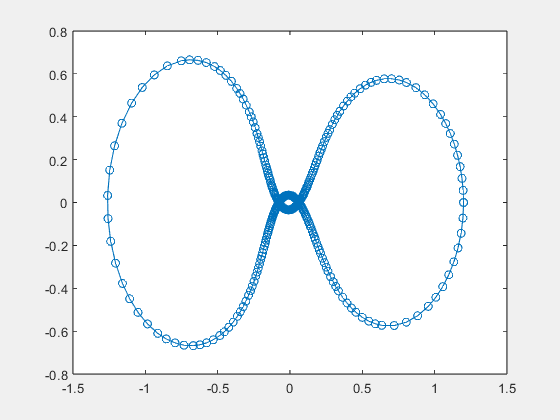

te =     0.0000
    3.0953
    6.1933


ye =     1.2000   -0.0000   -0.0000   -1.0494
   -1.2616   -0.0012   -0.0005    1.0485
    1.1989    0.0000   -0.0047   -1.0480


ie =      1
     2
     1


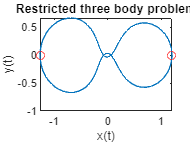

myOrbitode;

    Examining the documentation for `ode45()` , the additional parameters are defined as "find[ing] where functions of (*t*,*y*), called event functions, are zero. In the output, `te` is the time of the event, `ye` is the solution at the time of the event, and `ie` is the index of the triggered event." The figure titled restricted three-body problem shows the values of `ye `plotted along the solutions to the three-body problem themselves. 

  The values of `ye` are related to the y0 values because they both identify the values at which t is set to zero. This can be further supported by the way that  Similarly, the values ot `te` are bound by the values of `tspan`, as shown by how `te` seems to provide three points of interest for the event within the bound of `tspan`. Finally, `ie` explains which event takes place at each `te` found. Overall, these values provide more insight to the influence of `tspan` and `y0` along the orbitode problem. 

#### Problem 15: 

NOTE: `predatorPreyModel` can be found at the bottom

**Part a:**

% Given Values 
tmax = 10;
r0 = 300; f0 = 150; alpha = 0.01;

% ODE Solution
[t, y, tp] =  predatorPreyModel(r0, f0, alpha, tmax);
fprintf('tp = %.6f\n', tp);

tp = 5.029429


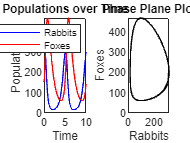


% Plotting
figure;
subplot(1,2,1);
plot(t, y(:,1), 'b', t, y(:,2), 'r');
title('Populations over Time');
xlabel('Time');
ylabel('Population');
legend('Rabbits', 'Foxes');

subplot(1,2,2);
plot(y(:,1), y(:,2), 'k');
title('Phase Plane Plot');
xlabel('Rabbits');
ylabel('Foxes');

**Part b: **

% Given Values 
tmax = 10;
r0 = 15; f0 = 22; alpha = 0.01;

% ODE Solution
[t, y, tp] =  predatorPreyModel(r0, f0, alpha, tmax);
fprintf('tp = %.6f\n', tp);

tp = 6.638688


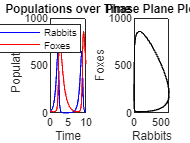


% Plotting
figure;
subplot(1,2,1);
plot(t, y(:,1), 'b', t, y(:,2), 'r');
title('Populations over Time');
xlabel('Time');
ylabel('Population');
legend('Rabbits', 'Foxes');

subplot(1,2,2);
plot(y(:,1), y(:,2), 'k');
title('Phase Plane Plot');
xlabel('Rabbits');
ylabel('Foxes');

**Part c: **

% Given Values 
tmax = 10;
r0 = 102; f0 = 198; alpha = 0.01;

% ODE Solution
[t, y, tp] =  predatorPreyModel(r0, f0, alpha, tmax);
fprintf('tp = %.6f\n', tp);

tp = 1.250000


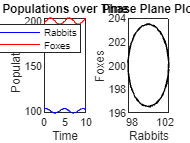


% Plotting
figure;
subplot(1,2,1);
plot(t, y(:,1), 'b', t, y(:,2), 'r');
title('Populations over Time');
xlabel('Time');
ylabel('Population');
legend('Rabbits', 'Foxes');

subplot(1,2,2);
plot(y(:,1), y(:,2), 'k');
title('Phase Plane Plot');
xlabel('Rabbits');
ylabel('Foxes');

#### **Part d:**


$$u(t) = r(t) - 1/\alpha\\
v(t) = f(t) - 2/\alpha$$


**Simplifying this to a Linear System, we get the following:**


$$\frac{du}{dt} = -u - (\alpha v)/2\\
\frac{dv}{dt} = u + v\\
\text{which is,}\\
\frac{d}{dt }
\pmatrix{u \cr v} = 
\pmatrix{-1 & -\alpha/2 \cr 1 & 1}\pmatrix{u \cr v}


$$


**Getting the Eigenvalues of this ODE, we get the following:**


$$det(A-\lambda I) = 0 \\
\lambda^2 - (1-1)\lambda + (-1)(1) - (-\alpha/2)(1) = 0 \\
\lambda^2 + 1 - (\alpha/2) = 0 \\
\text{which gives us the solution:} \\
\lambda = \pm i * (\sqrt{1-(\alpha/2})$$


#### Problem 16: 

NOTE: `newPredatorPreyModel` can be found at the bottom

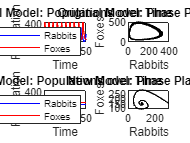

% Given Values 
tmax = 50; R = 400;
r0 = 300; f0 = 150; alpha = 0.01;

% Original Model
[t_orig, y_orig, ~] =  predatorPreyModel(r0, f0, alpha, tmax);

% New Model 
[t_new, y_new, ~] = newPredatorPreyModel(r0, f0, alpha, R, tmax);

% Plotting
figure;
subplot(2,2,1);
xbounds = [0, tmax];
ybounds = [0, 450];
plot(t_orig, y_orig(:,1), 'b', t_orig, y_orig(:,2), 'r');
title('Original Model: Populations over Time');
xlabel('Time');
ylabel('Population');
xlim(xbounds);
ylim(ybounds);
legend('Rabbits', 'Foxes');

subplot(2,2,2);
plot(y_orig(:,1), y_orig(:,2), 'k');
title('Original Model: Phase Plane Plot');
xlabel('Rabbits');
ylabel('Foxes');


subplot(2,2,3);
plot(t_new, y_new(:,1), 'b', t_new, y_new(:,2), 'r');
title('New Model: Populations over Time');
xlabel('Time');
ylabel('Population');
xlim(xbounds);
ylim(ybounds);
legend('Rabbits', 'Foxes');

subplot(2,2,4);
plot(y_new(:,1), y_new(:,2), 'k');
title('New Model: Phase Plane Plot');
xlabel('Rabbits');
ylabel('Foxes');

#### Problem 17:

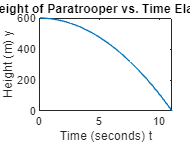

% Given Info
m = 80;       
g = 9.81;     
y0 = [600; 0]; 
tspan = [0, 25];

% K1 and K2 
K = [0, 0];

% ODE
a = @(t, y) (t < 5) * K(1) * y(2)^2 + (t >= 5) * K(2) * y(2)^2;
ydd = @(t, y) [y(2); -g + a(t, y)/m];
options = odeset('Events', @zeroCrossEvent);
[t, y, te, ye] = ode45(ydd, tspan, y0, options);

% Interpret Solution
figure; clf;
plot(t, y(:, 1));
title('Height of Paratrooper vs. Time Elapsed')
xlabel('Time (seconds) t');
ylabel('Height (m) y');

chute_opens_at = y(find(t >= 5, 1), 1);
idx = find(y < 0); 
hits_ground_at = te;
fprintf('Chute Opens at Height: %.5f m\n', chute_opens_at);

Chute Opens at Height: 471.14629 m


fprintf('Hits Ground at Height: %.5f seconds\n', hits_ground_at);

Hits Ground at Height: 11.06003 seconds


#### Problem18:

% determining trajectory of spherical cannonball in cartesian coords

#### Extra Functions:

myOrbitode

function myOrbitode
%ORBITODE  Restricted three body problem.
%   This is a standard test problem for non-stiff solvers stated in Shampine
%   and Gordon, p. 246 ff.  The first two solution components are
%   coordinates of the body of infinitesimal mass, so plotting one against
%   the other gives the orbit of the body around the other two bodies.  The
%   initial conditions have been chosen so as to make the orbit periodic.
%   Moderately stringent tolerances are necessary to reproduce the
%   qualitative behavior of the orbit.  Suitable values are 1e-5 for RelTol
%   and 1e-4 for AbsTol.
%
%   ORBITODE runs a demo of event location where the ability to
%   specify the direction of the zero crossing is critical.  Both
%   the point of return to the initial point and the point of
%   maximum distance have the same event function value, and the
%   direction of the crossing is used to distinguish them.
%
%   The orbit of the third body is plotted using the output function
%   ODEPHAS2.
%
%   L. F. Shampine and M. K. Gordon, Computer Solution of Ordinary
%   Differential Equations, W.H. Freeman & Co., 1975.
%
%   See also ODE45, ODE23, ODE113, ODESET, ODEPHAS2, FUNCTION_HANDLE.

%   Mark W. Reichelt and Lawrence F. Shampine, 3-23-94, 4-19-94
%   Copyright 1984-2014 The MathWorks, Inc.


fprintf('\nThis is an example of event location where the ability to\n');
fprintf('specify the direction of the zero crossing is critical.  Both\n');
fprintf('the point of return to the initial point and the point of\n');
fprintf('maximum distance have the same event function value, and the\n');
fprintf('direction of the crossing is used to distinguish them.\n\n');

fprintf('Calling ODE45 with event functions active...\n\n');

fprintf('Note that the step sizes used by the integrator are NOT\n');
fprintf('determined by the location of the events, and the events are\n');
fprintf('still located accurately.\n\n');

% Problem parameters
mu = 1 / 82.45;
mustar = 1 - mu;
y0 = [1.2; 0; 0; -1.04935750983031990726];
tspan = [0 7];

options = odeset('RelTol',1e-5,'AbsTol',1e-4,'OutputFcn',@odephas2,...
   'Events',@events);

figure;
[t,y,te,ye,ie] = ode45(@f,tspan,y0,options);
te
ye
ie

figure;
plot(y(:,1),y(:,2),ye(:,1),ye(:,2),'ro');
title('Restricted three body problem');
ylabel('y(t)');
xlabel('x(t)');

% -----------------------------------------------------------------------
% Nested functions -- problem parameters provided by the outer function.
%

   function dydt = f(t,y)
      % Derivative function -- mu and mustar shared with the outer function.
      r13 = ((y(1) + mu)^2 + y(2)^2) ^ 1.5;
      r23 = ((y(1) - mustar)^2 + y(2)^2) ^ 1.5;
      dydt = [ y(3)
         y(4)
         2*y(4) + y(1) - mustar*((y(1)+mu)/r13) - mu*((y(1)-mustar)/r23)
         -2*y(3) + y(2) - mustar*(y(2)/r13) - mu*(y(2)/r23) ];
   end

% -----------------------------------------------------------------------

   function [value,isterminal,direction] = events(t,y)
      % Event function -- y0 shared with the outer function.
      % Locate the time when the object returns closest to the initial point y0
      % and starts to move away, and stop integration.  Also locate the time when
      % the object is farthest from the initial point y0 and starts to move closer.
      %
      % The current distance of the body is
      %
      %   DSQ = (y(1)-y0(1))^2 + (y(2)-y0(2))^2 = <y(1:2)-y0(1:2),y(1:2)-y0(1:2)>
      %
      % A local minimum of DSQ occurs when d/dt DSQ crosses zero heading in
      % the positive direction.  We can compute d/dt DSQ as
      %
      %   d/dt DSQ = 2*(y(1:2)-y0)'*dy(1:2)/dt = 2*(y(1:2)-y0)'*y(3:4)
      %
      % y0 is shared with the outer function.
      
      dDSQdt = 2 * ((y(1:2)-y0(1:2))' * y(3:4));
      value = [dDSQdt; dDSQdt];
      isterminal = [1;  0];         % stop at local minimum
      direction  = [1; -1];         % [local minimum, local maximum]
   end

% -----------------------------------------------------------------------

end  % orbitode

predatorPreyModel

function [t, y, tp] = predatorPreyModel(r0, f0, alpha, tmax)
    
    % ODE Solution
    tspan = [0, tmax];
    dydt = @(t, y) [2*y(1) - alpha*y(1)*y(2); -y(2) + alpha*y(1)*y(2)];
    [t, y] = ode45(dydt, tspan, [r0, f0]);
    tp = find_period(t, y, [r0, f0]);

    % Convert
    function dydt = odefcn(t, y, alpha)
        dydt = [2*y(1) - alpha*y(1)*y(2); -y(2) + alpha*y(1)*y(2)];
    end
    
    % Finding tp
    function tp = find_period(t, y, initial_conditions)
        tol = 0.04 * max(initial_conditions);
        startIdx = find(t > 0, 1); 
    
        % Initialize tp as a large number
        tp = max(t);
    
        % Loop over the solution, starting after the initial time
        for i = startIdx:length(t)
            if abs(y(i,1) - initial_conditions(1)) <= tol && ...
               abs(y(i,2) - initial_conditions(2)) <= tol && ...
               t(i) > 0.1*max(t)
                tp = t(i);
                break; 
            end
        end
    end

end

newPredatorPreyModel

function [t, y, tp] = newPredatorPreyModel(r0, f0, alpha, R, tmax)
    
    % ODE Solution
    tspan = [0, tmax];
    dydt = @(t, y) [2*(1 - y(1)/R)*y(1) - alpha*y(1)*y(2); -y(2) + alpha*y(1)*y(2)];
    [t, y] = ode45(dydt, tspan, [r0, f0]);
    tp = find_period(t, y, [r0, f0]);

    % Finding tp
    function tp = find_period(t, y, initial_conditions)
        tol = 0.04 * max(initial_conditions);
        startIdx = find(t > 0, 1); 
    
        % Initialize tp as a large number
        tp = max(t);
    
        % Loop over the solution, starting after the initial time
        for i = startIdx:length(t)
            if abs(y(i,1) - initial_conditions(1)) <= tol && ...
               abs(y(i,2) - initial_conditions(2)) <= tol && ...
               t(i) > 0.1*max(t)
                tp = t(i);
                break; 
            end
        end
    end

end

zeroCrossEvent


% Event function to detect zero crossing of y(:, 1)
function [value, isterminal, direction] = zeroCrossEvent(t, y)
    value = y(1);    
    isterminal = 1;   
    direction = 0;  
end